% 1a
par = 0.1;
a = 0; b = 2*pi;
x = linspace(a,b,100);

grid on
y =  exp(-par.*x.*x).*cos(x.*x)

y =     1.0000    0.9996    0.9983    0.9957    0.9915    0.9850    0.9753    0.9614    0.9423    0.9168    0.8836    0.8415    0.7893    0.7260    0.6508    0.5632    0.4635    0.3521    0.2305    0.1007   -0.0344   -0.1709   -0.3043   -0.4293   -0.5401   -0.6309   -0.6959   -0.7299   -0.7291   -0.6912   -0.6161   -0.5063   -0.3671   -0.2065   -0.0351    0.1344    0.2886    0.4141    0.4992    0.5353    0.5181    0.4488    0.3344    0.1876    0.0256   -0.1319   -0.2646   -0.3550   -0.3912   -0.3687


f = @(x) exp(-par.*x.*x).*cos(x.*x)

f = function_handle with value:
    @(x)exp(-par.*x.*x).*cos(x.*x)


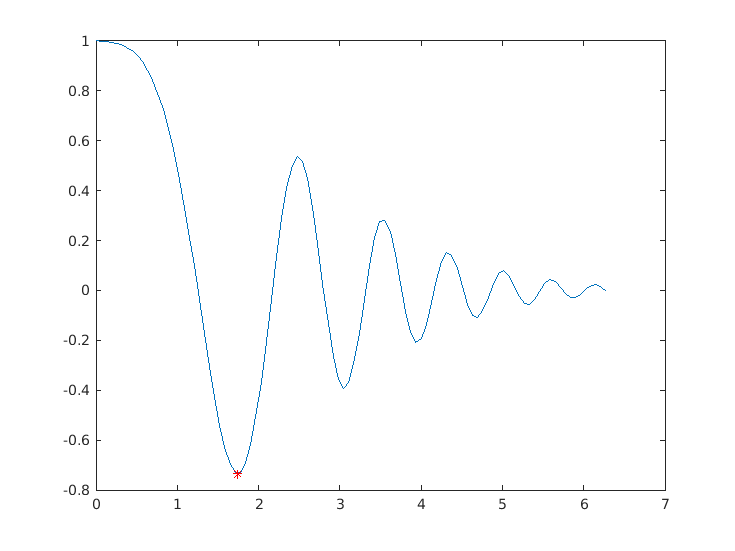

plot(x,y)

z = ginput(2);
[minx, miny] = fminbnd(f,z(1,1),z(2,1));
hold on;
plot(minx, miny,'r*');
hold off

% 1b
a1 = 1; b1 = 2;
a = 0; b = 2*pi/3

b = 2.0944

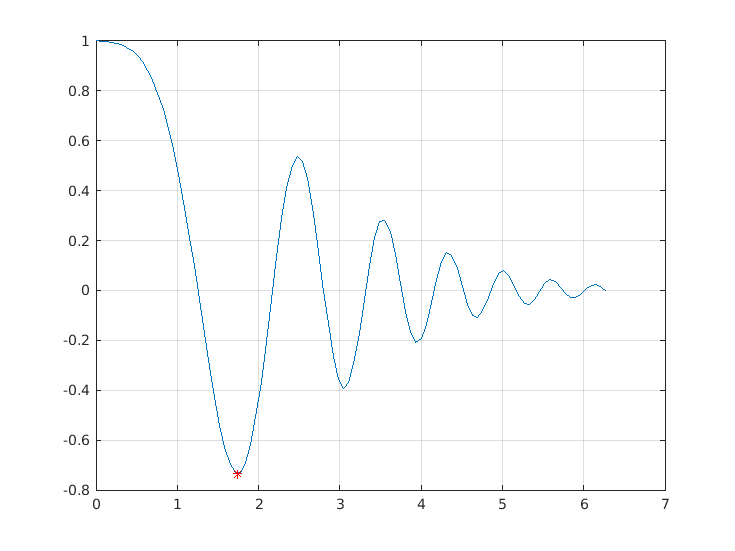

x = linspace(a,b,100);

grid on

y =  1./(a1.*cos(x)+b1.*sin(x)).^2

y =     1.0000    0.9209    0.8515    0.7904    0.7362    0.6880    0.6450    0.6064    0.5717    0.5403    0.5119    0.4861    0.4626    0.4412    0.4216    0.4036    0.3870    0.3718    0.3578    0.3449    0.3330    0.3219    0.3117    0.3022    0.2934    0.2852    0.2776    0.2706    0.2640    0.2579    0.2522    0.2470    0.2421    0.2376    0.2334    0.2295    0.2259    0.2226    0.2196    0.2168    0.2143    0.2120    0.2099    0.2080    0.2063    0.2049    0.2036    0.2026    0.2017    0.2010


f = @(x) 1./(a1.*cos(x)+b1.*sin(x)).^2

f = function_handle with value:
    @(x)1./(a1.*cos(x)+b1.*sin(x)).^2


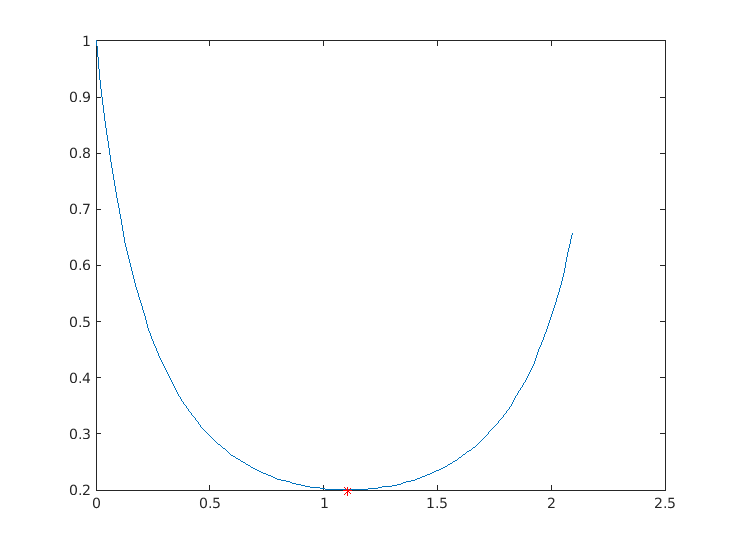

plot(x,y)

z = ginput(2);
[minx, miny] = fminbnd(f,z(1,1),z(2,1));
hold on;
plot(minx, miny,'r*');
hold off

%1d
clear
a = 0; b = 2*pi

b = 6.2832

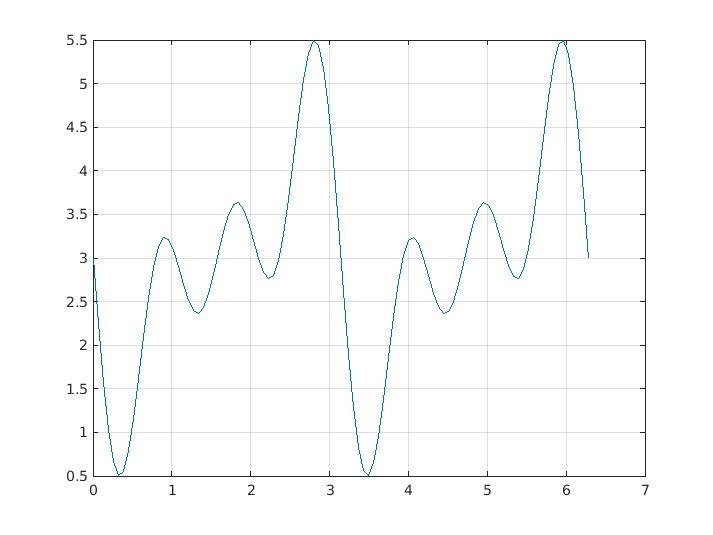

x = linspace(a,b,100);

grid on

y=0;
m = input("Введите число");
for i=1:m
    A(i)=i;
    y = y + (cos(i.*x)-sin(i*x)).^2
end

y =     1.0000    0.8734    0.7489    0.6283    0.5138    0.4071    0.3099    0.2239    0.1503    0.0904    0.0451    0.0152    0.0011    0.0031    0.0212    0.0550    0.1040    0.1674    0.2443    0.3332    0.4329    0.5418    0.6580    0.7797    0.9049    1.0317    1.1580    1.2817    1.4009    1.5137    1.6182    1.7127    1.7958    1.8660    1.9224    1.9638    1.9898    1.9999    1.9938    1.9718    1.9341    1.8815    1.8146    1.7346    1.6428    1.5406    1.4298    1.3120    1.1893    1.0634


y =     2.0000    1.6223    1.2627    0.9383    0.6641    0.4522    0.3111    0.2451    0.2543    0.3346    0.4780    0.6732    0.9061    1.1611    1.4221    1.6732    1.8998    2.0898    2.2341    2.3271    2.3671    2.3563    2.3008    2.2095    2.0942    1.9683    1.8460    1.7411    1.6663    1.6322    1.6463    1.7128    1.8319    2.0000    2.2097    2.4502    2.7081    2.9681    3.2141    3.4300    3.6009    3.7140    3.7596    3.7314    3.6276    3.4503    3.2059    2.9049    2.5609    2.1900


y =     3.0000    2.2506    1.5726    1.0286    0.6652    0.5072    0.5553    0.7868    1.1592    1.6164    2.0962    2.5392    2.8959    3.1330    3.2367    3.2138    3.0890    2.9005    2.6934    2.5125    2.3953    2.3665    2.4347    2.5913    2.8125    3.0634    3.3042    3.4968    3.6113    3.6311    3.5560    3.4029    3.2036    3.0000    2.8380    2.7601    2.7985    2.9693    3.2691    3.6743    4.1427    4.6190    5.0413    5.3496    5.4936    5.4401    5.1778    4.7195    4.1016    3.3793


    f = @(x) sum((cos(A.*x)-sin(A*x)).^2)

f = function_handle with value:
    @(x)sum((cos(A.*x)-sin(A*x)).^2)


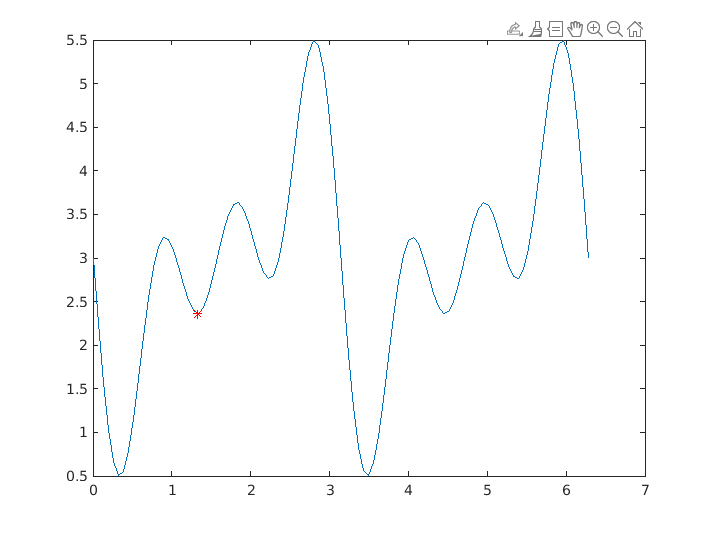

plot(x,y)

z = ginput(2);
[minx, miny] = fminbnd(f,z(1,1),z(2,1));
hold on;
plot(minx, miny,'r*');
hold off

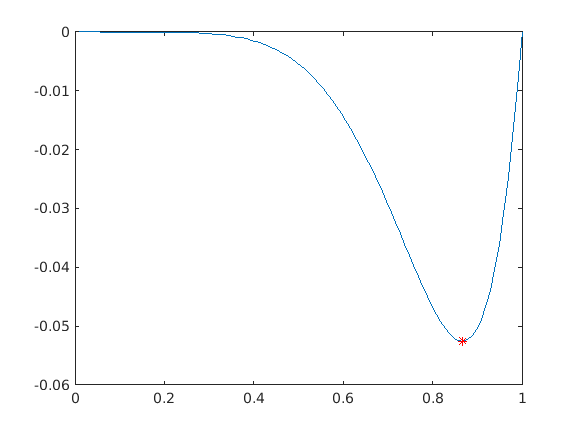

% 2a
a = 7;
x = linspace(0, 1, 100);
y = x.^a.*log(x);
f = @(x) x.^a.*log(x);
plot(x, y);
[minx, miny] = fminbnd(f,x(1),x(100));
hold on;
plot(minx, miny,'r*');
hold off;

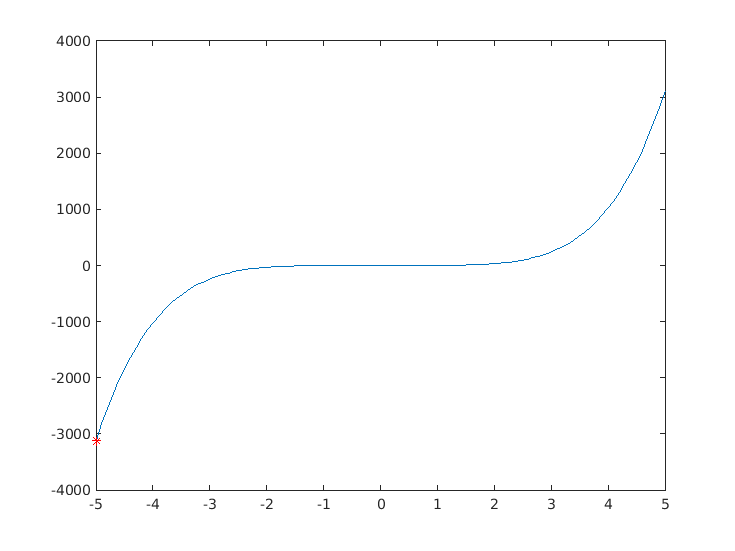

% 2b
a = 5;
b = 0;
x = linspace(-5, 5, 100);
y = x.^a.*exp(-b.*x);
f = @(x) x.^a.*exp(-b.*x);
plot(x, y);
[minx, miny] = fminbnd(f,x(1),x(100));
hold on;
plot(minx, miny,'r*');
hold off;

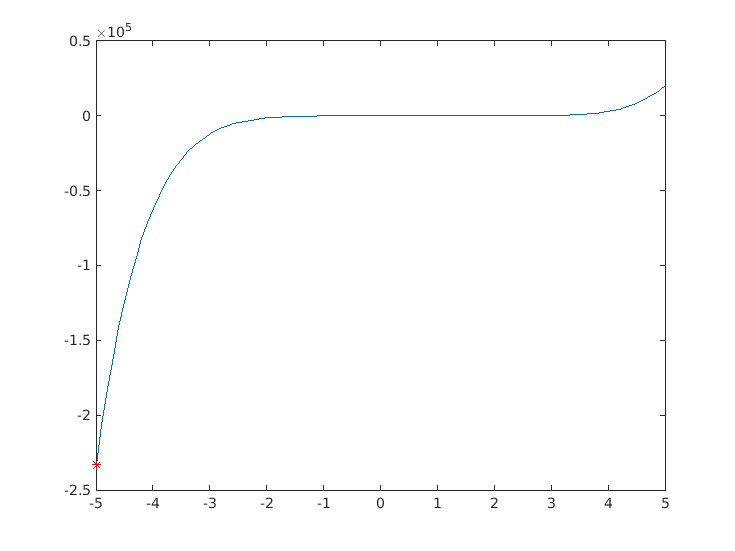

% 2c
a = 1;
b = 6;
x = linspace(-5, 5, 100);
y = (x.^a).*((1-x).^b);
f = @(x) (x.^a).*((1-x).^b);
plot(x, y);
[minx, miny] = fminbnd(f,x(1),x(100));
hold on;
plot(minx, miny,'r*');
hold off;